## Homework 4

**2411374 朱灏轩**

### Question

MD simulation of a Lenard-Jones system

According to what you learned, write an MD program with parameters:

- Temperature $T=0.25$

- Time stemp $h=0.01$

- Use the initial position and velocity, as shown

- Number of particle $np=4\times 4\times 4$, mass of particle $m=1$

- steps of simulation $mm_{step}=15000$

- Your code must be executable, and can display particle positions in time

- Display your final averaged nearest-neighbor distance

Calculate the final averaged nearest-neighbor distance.

Calculate the pressure.


$$\text{system volumn} = \text{particle number}\times (\text{average nearest-neighbor distance})^3$$


### Solution

根据题设条件设定程序变量

% Parameters
T = 0.25;               % Temperature
h = 0.01;               % Time step
np = 4 * 4 * 4;         % Number of particles
m = 1;                  % Mass of each particle
n_steps = 15000;        % Number of simulation steps
L = 100;           % Approximate length of the cubic simulation box

设定粒子初始位置及速度

% Initialize positions and velocities
rng(1);                 % Seed for reproducibility
positions = L * rand(np, 3);  % Random initial positions in a box
velocities = sqrt(T) * randn(np, 3); % Maxwell-Boltzmann distribution

设定 Lenard-Jones 算法参数

% Lennard-Jones potential parameters
epsilon = 1.0;
sigma = 1.0;

为了展示不同时间点时粒子的分布情况，此处在模拟时间范围内均匀选择五个时间点，绘制粒子分布情况

% Define the sampling points for plotting (5 time points)
sampling_points = linspace(1, n_steps, 5);

使用 Lenard-Jones 及 Verlet 算法进行分子动力学模拟并绘制图像

为了更好地展现粒子在不同时间点地分布情况，此处设定坐标轴区间为 $[0, 100]$

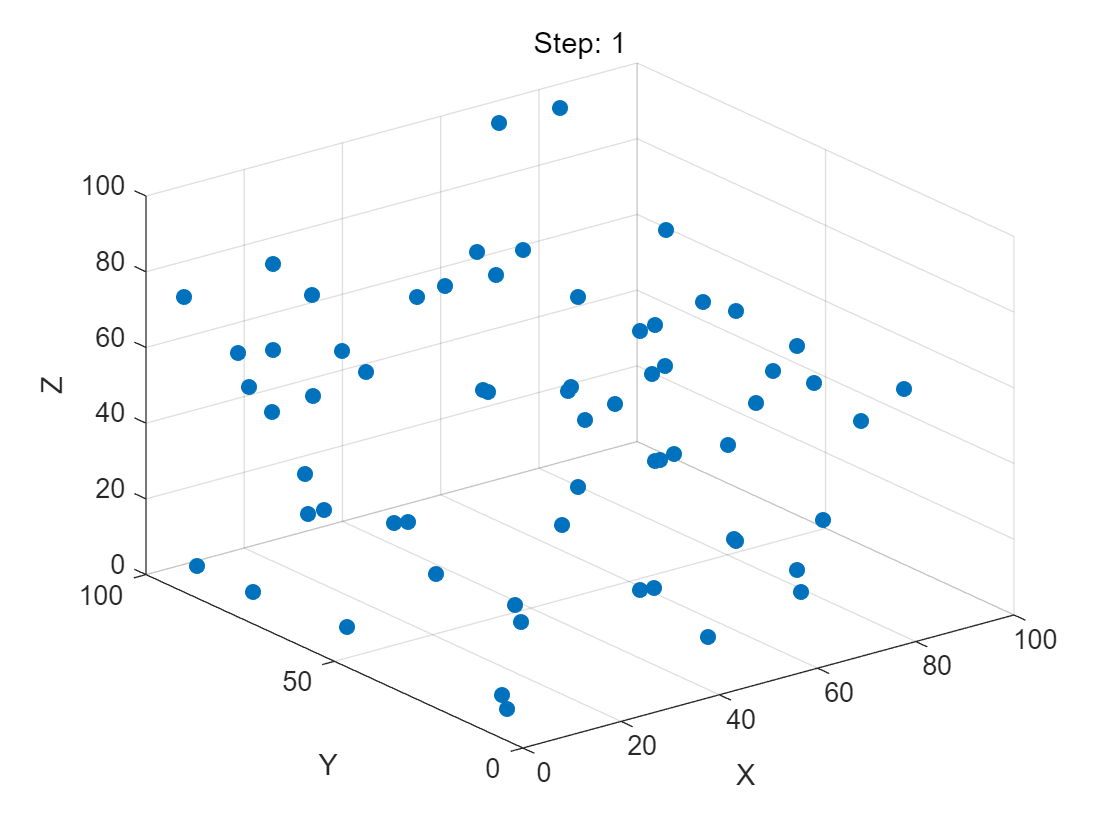

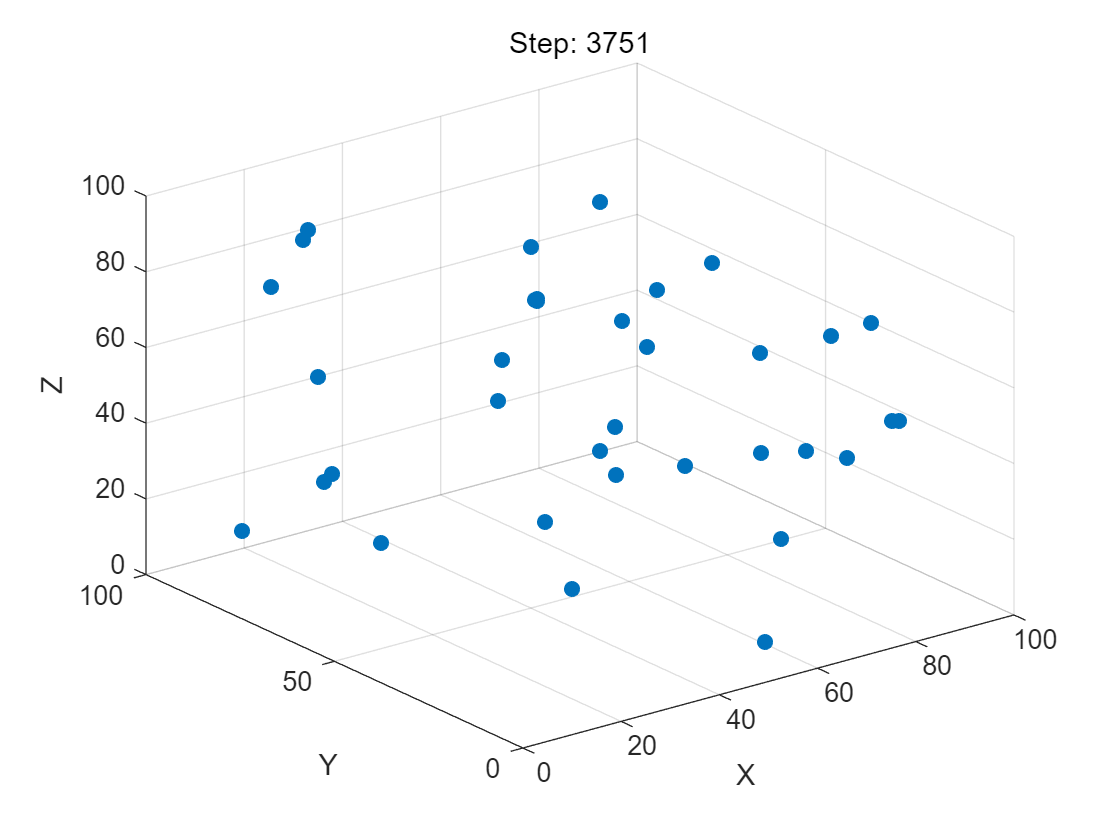

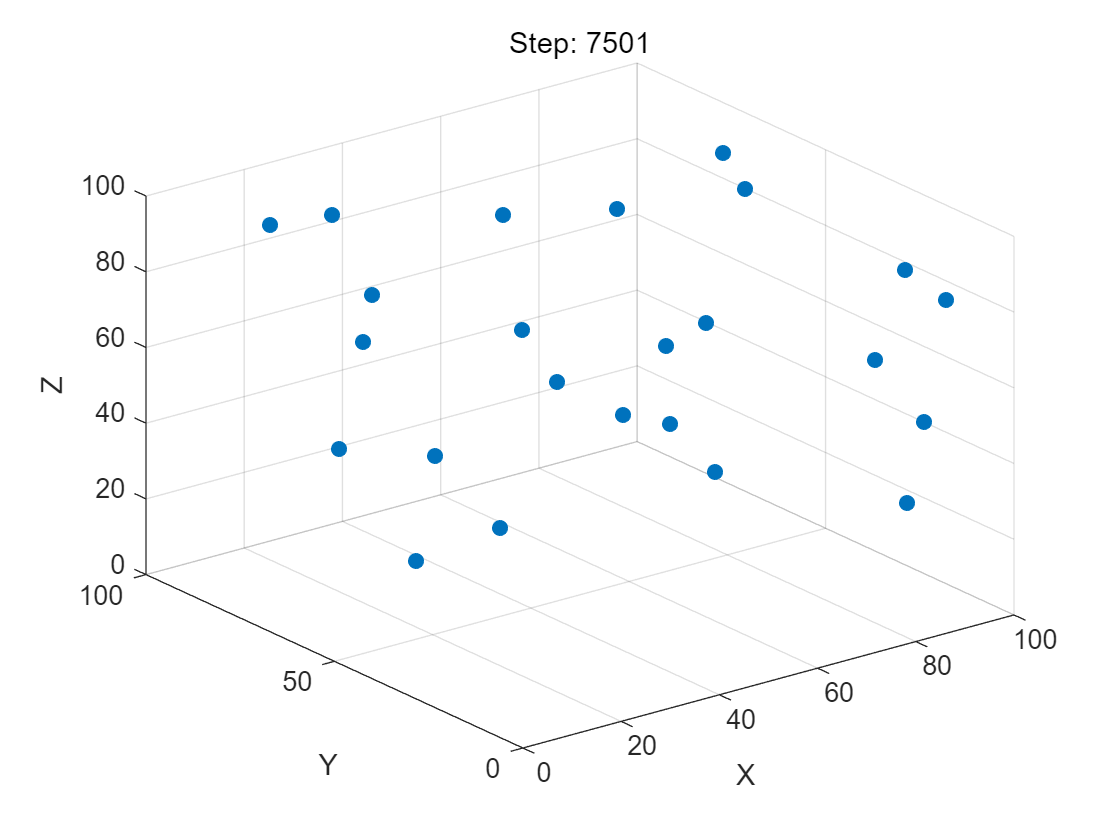

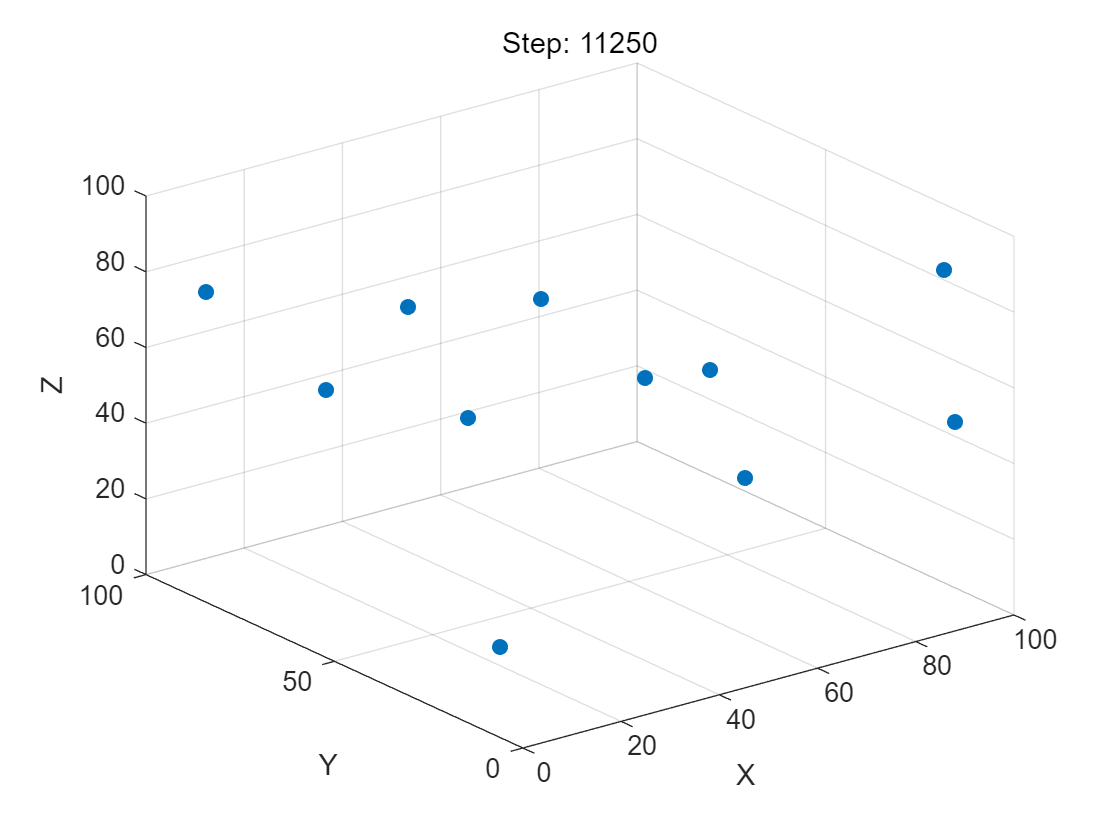

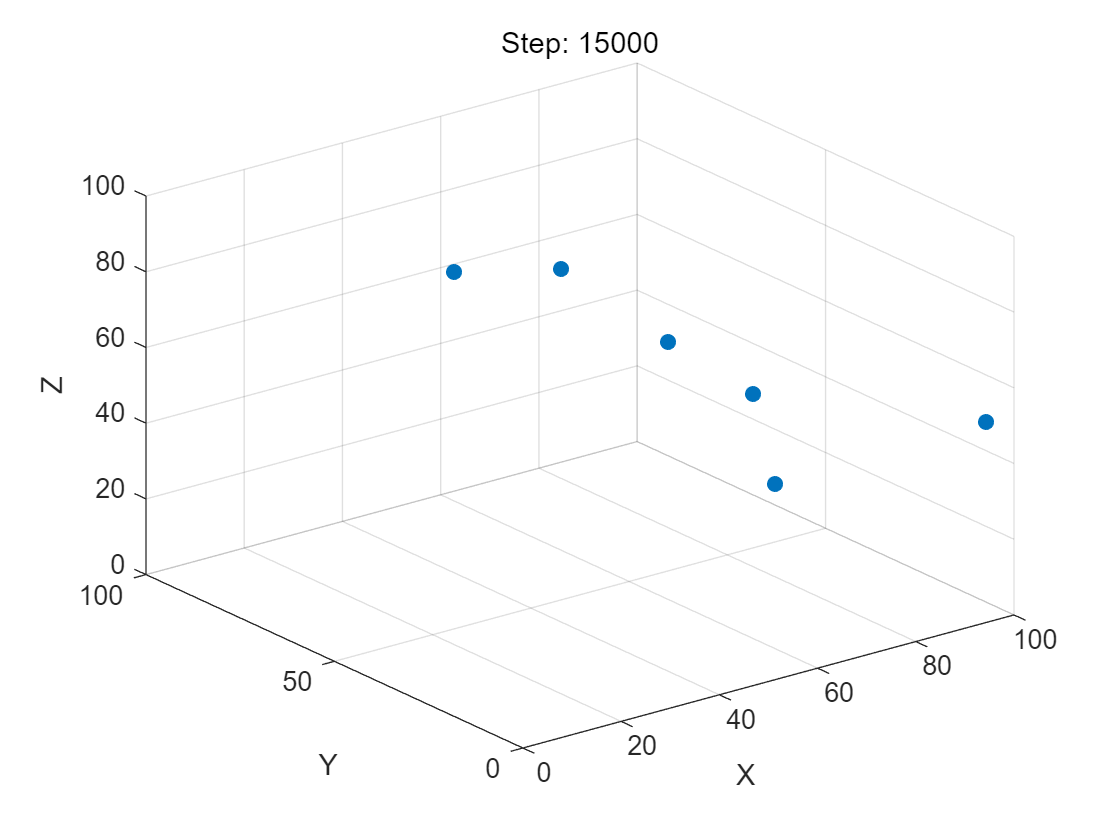

% Main MD loop
for step = 1:n_steps
    % Calculate forces and update positions
    forces = zeros(np, 3);
    for i = 1:np
        for j = i+1:np
            r_ij = positions(i, :) - positions(j, :);
            r = norm(r_ij);
            if r < 2.5 * sigma % Cut-off distance
                % Lennard-Jones force
                F = 48 * epsilon * (sigma^12 / r^13 - 0.5 * sigma^6 / r^7) * (r_ij / r);
                forces(i, :) = forces(i, :) + F;
                forces(j, :) = forces(j, :) - F;
            end
        end
    end

    % Velocity Verlet integration
    velocities = velocities + 0.5 * (forces / m) * h;
    positions = positions + velocities * h;
    forces = zeros(np, 3);
    for i = 1:np
        for j = i+1:np
            r_ij = positions(i, :) - positions(j, :);
            r = norm(r_ij);
            if r < 2.5 * sigma % Cut-off distance
                F = 48 * epsilon * (sigma^12 / r^13 - 0.5 * sigma^6 / r^7) * (r_ij / r);
                forces(i, :) = forces(i, :) + F;
                forces(j, :) = forces(j, :) - F;
            end
        end
    end
    velocities = velocities + 0.5 * (forces / m) * h;

    % Plot the particle positions at specific sampling points
    if ismember(step, round(sampling_points))
        figure;
        scatter3(positions(:,1), positions(:,2), positions(:,3), 36, 'filled');
        title(['Step: ', num2str(step)]);
        xlabel('X'); ylabel('Y'); zlabel('Z');
        xlim([0, L]);
        ylim([0, L]);
        zlim([0, L]);
        grid on;
    end
end

计算平均最短距离及气压

% Calculate nearest-neighbor distance
distances = pdist(positions);
nearest_neighbor_distance = mean(min(squareform(distances) + eye(np) * max(distances(:))));

% Calculate system volume and pressure
system_volume = np * nearest_neighbor_distance^3;
pressure = np * T / system_volume; % Ideal gas approximation

% Display results
disp(['Final averaged nearest-neighbor distance: ', num2str(nearest_neighbor_distance)]);

Final averaged nearest-neighbor distance: 50.5848


disp(['Pressure: ', num2str(pressure)]);

Pressure: 1.9314e-06
